# Boundary Conditions: Dirichlet BC

clear, close all, clc
set_defaults()

## Dimensional problem

Initially we neglect the spherical cap geometry and simply assume a linear domain (for now!). A steady confined groundwater aquifer across the entire southern highlands leads following governing equations

$-\frac{\mathrm{d}}{\mathrm{d}x}\left[bK\frac{\mathrm{d}h}{\mathrm{d}x}\right] = f_s$ for $x\in\left[0,\,l\right]$,

where $b$ is the thickness of the aquifer and $f_s$ is the precipitation. The boundary conditions are given by:

- $\left.\frac{\mathrm{d}h}{\mathrm{d}x}\right|_0=0$ - due to the symmetry at the south pole

- $h(x=l) = h_o$ - ocean level at dichotomy

The analytical solution is given by


$$h(x)=h_o + \frac{f_s\,l^2}{2bK}\left(1-\left(\frac{x}{l}\right)^2\right)$$


Assume the following problem paramters:

yr2s = 60^2*24*365.25; % second per year
rho = 1e3;      % [kg/m^3] desity of water 
grav = 3.711;   % [m/s^2] grav. acceleration on Mars
k = 1e-11;      % [m^2] permeability (Hanna & Phillips 2005)
mu = 1e-3;      % [Pa s] water viscosity
b = 5e3;
precip = 0.13;         % [mm/yr] equatorial precipitation (Andrews-Hanna 2010)
theta_bnd = acos(1/3); % [rad] co-lattitude of dichotomy bnd
R = 3389508;           % [m] radius of mars
ho = -500;             % [m] sealevel (for now)


Derived quantities

K = k*rho*grav/mu      % [m/s] hydraulic conductivity

K = 3.7110e-05

fp = precip/1e3/yr2s   % [m/s] precipitation 

fp = 4.1195e-12

l = R*(pi-theta_bnd)    % [m] distance from south pole to dichotomy bnd

l = 6.4761e+06


xdim = linspace(0,l,1e2);
hdim = @(x) ho + fp*l^2/(2*b*K)*(1-(x/l).^2);

subplot 121
plot(xdim/1e3,hdim(xdim))
pbaspect([1 .8 1])
xlabel('x [km]')
ylabel('h [m]')
title('Dimensional solution')

## Dimensionless problem

Introducing the following scales for the variables

$h' = \frac{h-h_o}{f_s\,l^2/bK} $ and $x'=\frac{x}{l}$

we have the following dimensionless governing equation

$-\frac{\mathrm{d}^2h'}{\mathrm{d}{x'}^{2}} = 1$  for $x'\in\left[0,\,1\right]$

with the boundary conditions

- 
$$\left.\frac{\mathrm{d}h'}{\mathrm{d}x'}\right|_{x'=0} = 0$$


- 
$$h'(x'=1) = 0$$


The dimensionless analytic solution is given by

$h'(x')=\frac{1}{2}\left(1-{x'}^2\right)$.

Below we will be solving the dimensionless system.

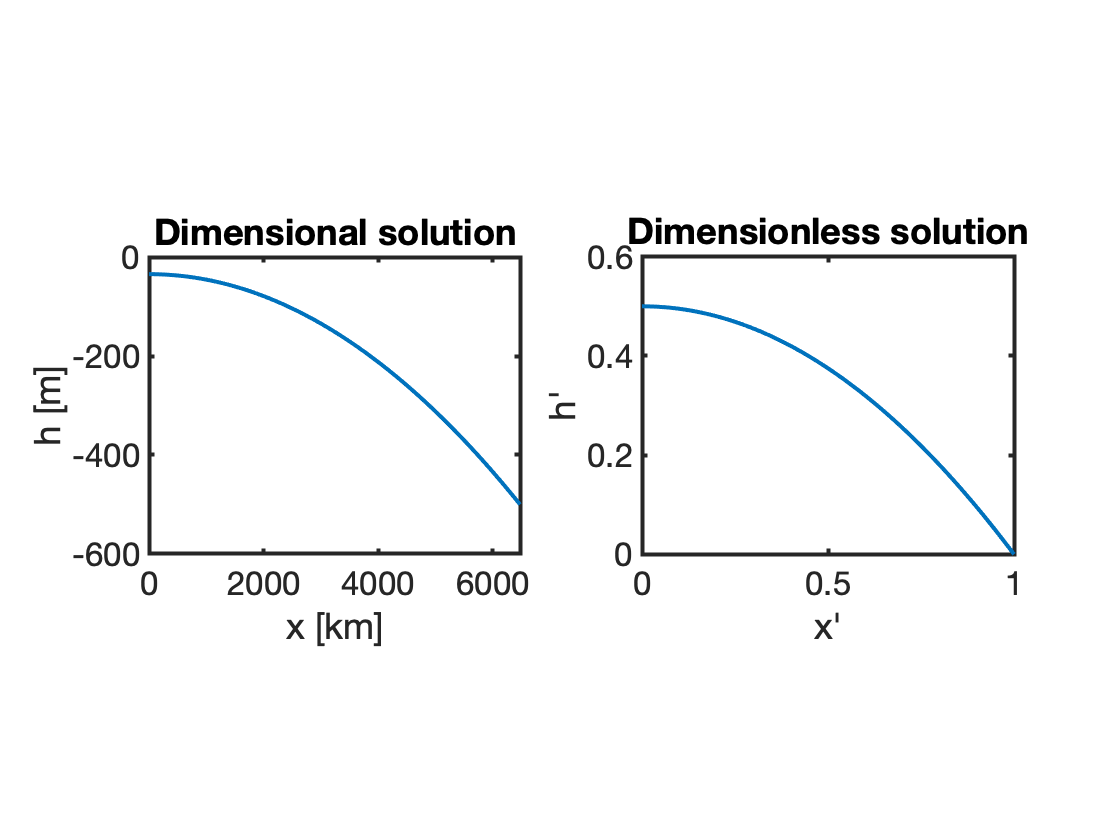

hprime = @(xprime) .5*(1-xprime.^2);
xprime = linspace(0,1,1e2);

subplot 122
plot(xprime,hprime(xprime))
pbaspect([1 .8 1])
xlabel('x''')
ylabel('h''')
title('Dimensionless solution')

# Imposing Dirichlet BC's by eliminating constraints

## Building the system matrix L

Using discrete operators the partial differential equation can be discretized as follows

`L``*``u ``=`` fs`

where `L = -D*G` is the dicrete Laplacian operator, **u** is the unknown vector of temperatures and `fs` is the right hand side vector. Today we will discuss how to discretize the boundary condtions.

Without boundary conditions the problem is ill-posed and does not have a solution. This is reflected in the condition number of the discrete Laplacian operator, `L`.  

Grid.xmin = 0; Grid.xmax =1; Grid.Nx = 20;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
L = -D*G; 
condest(L)

ans = Inf

A matrix with infinite condition number has no inverse. This is because there is an infinite number of possible solutions to the Laplace equation, only the boundary conditions (BC's) make the solution unique. 

## Dirichlect BC's as a linear system

Dirichlet BC's prescribe the solution on the boundary. In the discrete solution they prescribe the solution in the cells neighboring the boundaries. This constraint can be formulated as a linear system,

`B``*``u ``=`` g`

where `B` is the constrain matrix, `u` is the vector of unknowns (temperature), and **g** is a right hand side vector. The constrain matrix `B` is `Nc` by `Nx`, where `Nc` is the number of constraints, i.e., cells along Dirichlet boundaries with prescibed temperatures. This means that Dirichlet BC's provide constraints that reduce the overall number of unknown we need to solve for.

Therefore the boundary value problem is described by two linear systems

1) `L``*``u`` = ``fs`, arising from the PDE, where `L` is the `Nx` by `Nx` ***system matrix***

2) `B``*``u`` = ``g`, arising from the BC's, where **B** is the `Nc` by `Nx` ***constraint matrix***

Neither **L** nor **B** is invertible, both allow infinite solutions. To find the unique solution to the boundary value problem, the constraints in `B` must be eliminated from the system matrix `L`.

$\Rightarrow$**we need to understand how to eliminate constraints**

## Building the constraint matrix

Suppose we have the following two Nc by 1 column vectors:

- `dof_dir`: contains the degrees of fredom (dofs), i.e., cell numbers, of all cells along the Dirichlet boundary.

- `g`: contains the prescribed values the unknown is set to along the Dirichlet boundary.

The constraint matrix, **B**, needs to set the unknown in `dof_dir` to `g`. The matrix B therefore comprises the rows of the Nx by Nx identity matrix, `I`, that correspond to `dof_dir`. Therefore `B` can be built as follows

dof_dir = [Grid.dof_xmax];
B = I(dof_dir,:);
size(B)

ans =      1    20


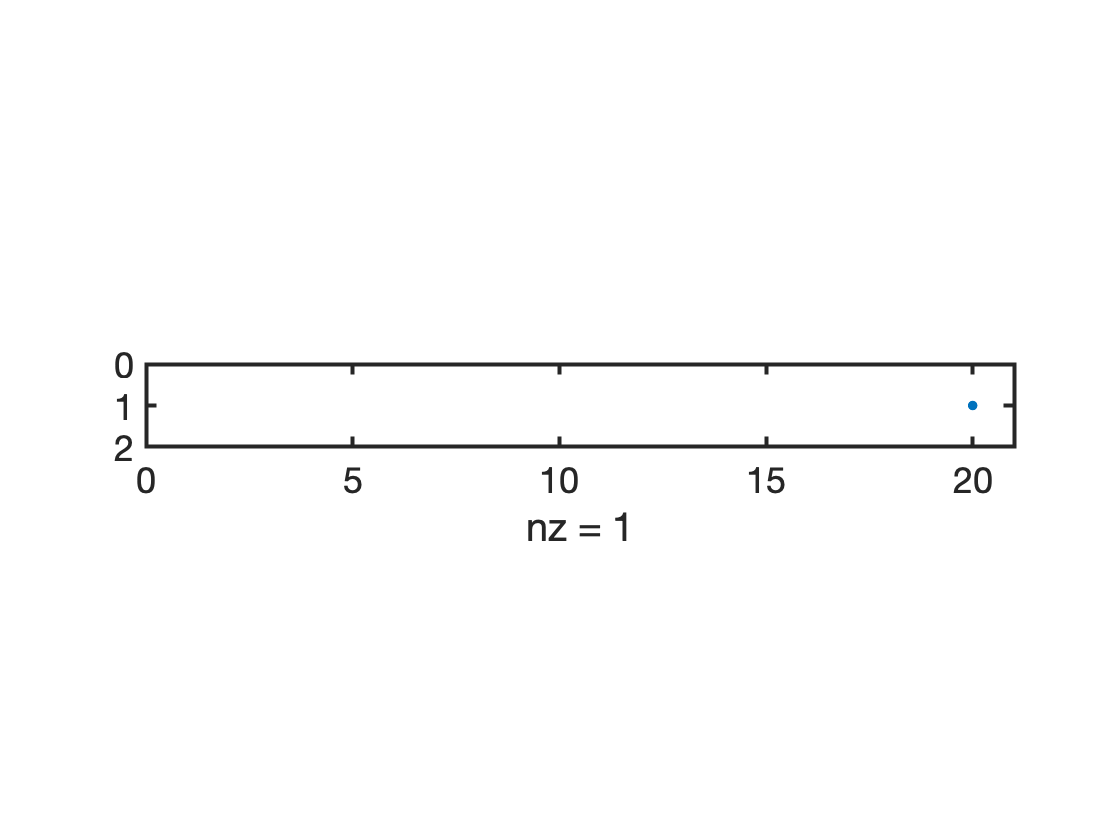

clf
spy(B)

The resulting constraint matrix has one row for every cell that is set to a prescribed value by the Dirichlet BC's. In the 1D case with Dirichlet BC's at one ends `Nc = 1` and `B` only has 1 rows. This simple construction will remain the same, even in higher dimensions.

# Homogeneous constraints

Initially, we consider a problem with homogeneous constraints, i.e., $T_0=0$.  The discrete problem is then given by

PDE: `L``*``u`` = ``fs`

BC's: `B``*``u`` = ``0`

## **Reduced linear system**

Given that the constraints in `B` reduce the number of unknown we expect to solve a smaller or reduced linear system of size `(Nx-Nc)` by `(Nx-Nc)`

`Lr``*``ur ``=`` fsr.`

Here the variables are:

- `ur` is the (Nx-Nc) by 1 reduced vector of unknows.

- `fsr` is the (Nx-Nc) by 1 reduced r.h.s. vector.

- `Lr` is the (Nx-Nc) by (Nx-Nc) reduced system matrix.

## Projection matrix

What is the relation between `u` and `ur`, `fs` and `fsr`, and `L` and `Lr`? Two vectors of different length are related by a rectangular matrix

`u`` = ``N``*``ur` and `fs`` = ``N``*``fsr`

where `N` is a Nx by (Nx-Nc) matrix. Here **N** is any basis for the [nullspace](https://ocw.mit.edu/courses/mathematics/18-06-linear-algebra-spring-2010/video-lectures/lecture-6-column-space-and-nullspace/) of the constraint matrix **B**. The nullspace of **B** is simply the set of all solutions that satisfy `B``*``u`` = ``0`, i.e., all the possible solutions that satisfy the homogeneous boundary conditions.  If we search for solutions to `L``*``u``=``fs` in the nullspace of **B**, then the BC's are automatically satisfied. In Matlab the nullspace of a matrix can be found with the function [null()](https://www.mathworks.com/help/matlab/ref/null.html) or [spnull()](https://www.mathworks.com/matlabcentral/fileexchange/27550-sparse-null-space-and-orthogonal?focused=5152745&tab=function) for sparse matrices.

N = spnull(B);
size(N)

ans =     20    19


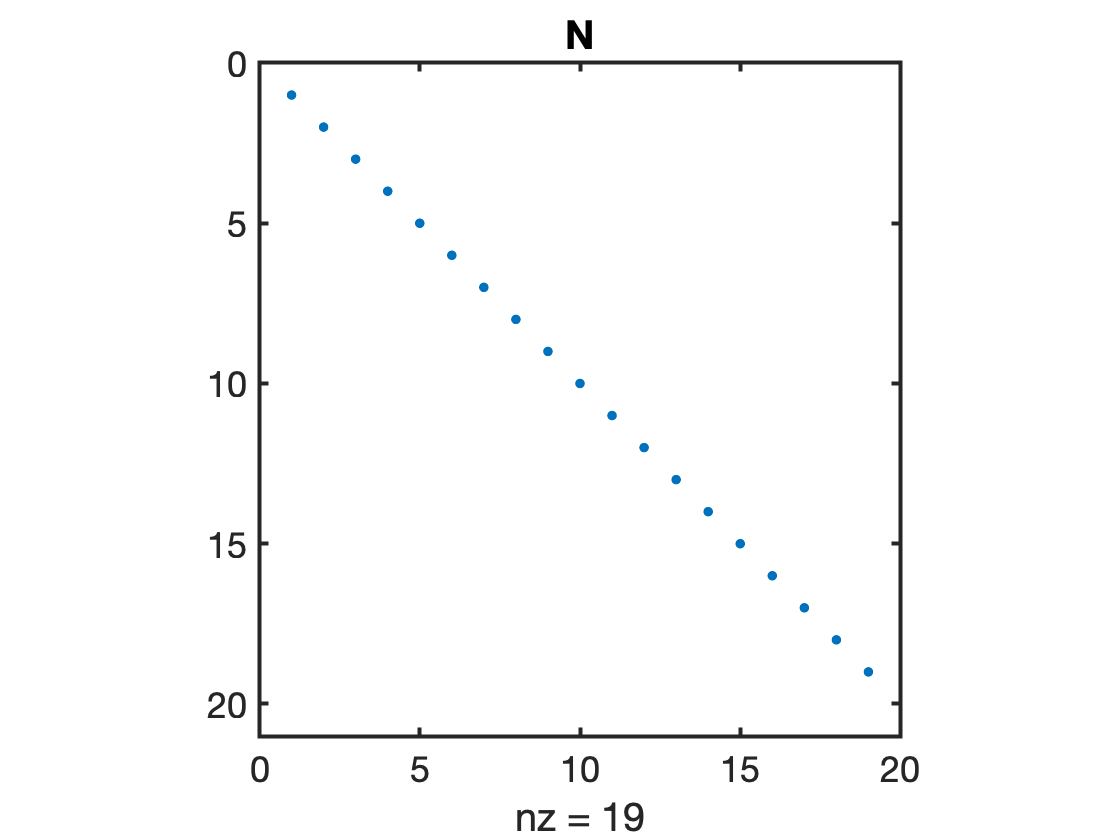

spy(N), title 'N'

Assume that `N` is orthonormal, i.e., that the dot product between all columns is unity. the it follows that

- `N'``*``N`` = ``Ir`, where `Ir` is the `(Nx-Nc)` by `(Nx-Nc)` identity matrix in the reduced space.

- **N*****N'** = **Ic**, where Ic is the `Nx` by `Nx` "identity matrix" with `Nc` zeros on the diagonal.

Ir = N'*N;
size(Ir)

ans =     19    19


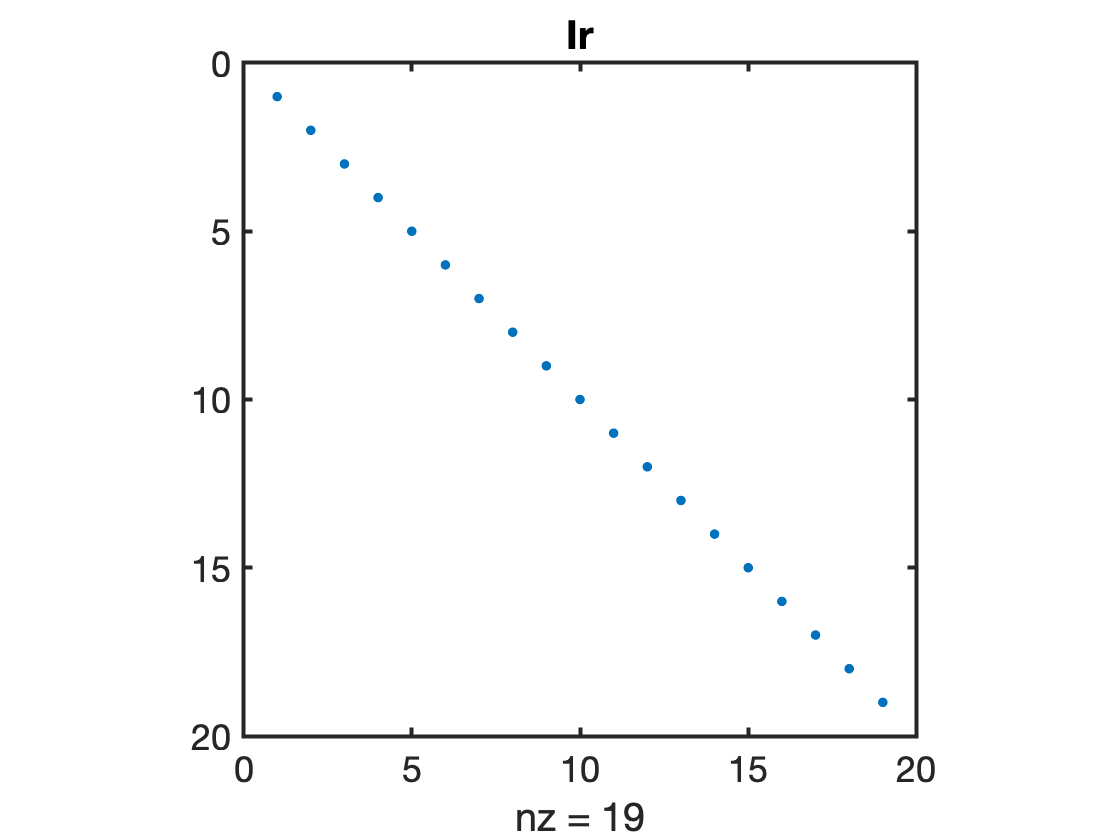

spy(Ir), title 'Ir'

non_0_entries_Ir = full(sum(diag(Ir)))

non_0_entries_Ir = 19


Ic = N*N';
size(Ic)

ans =     20    20


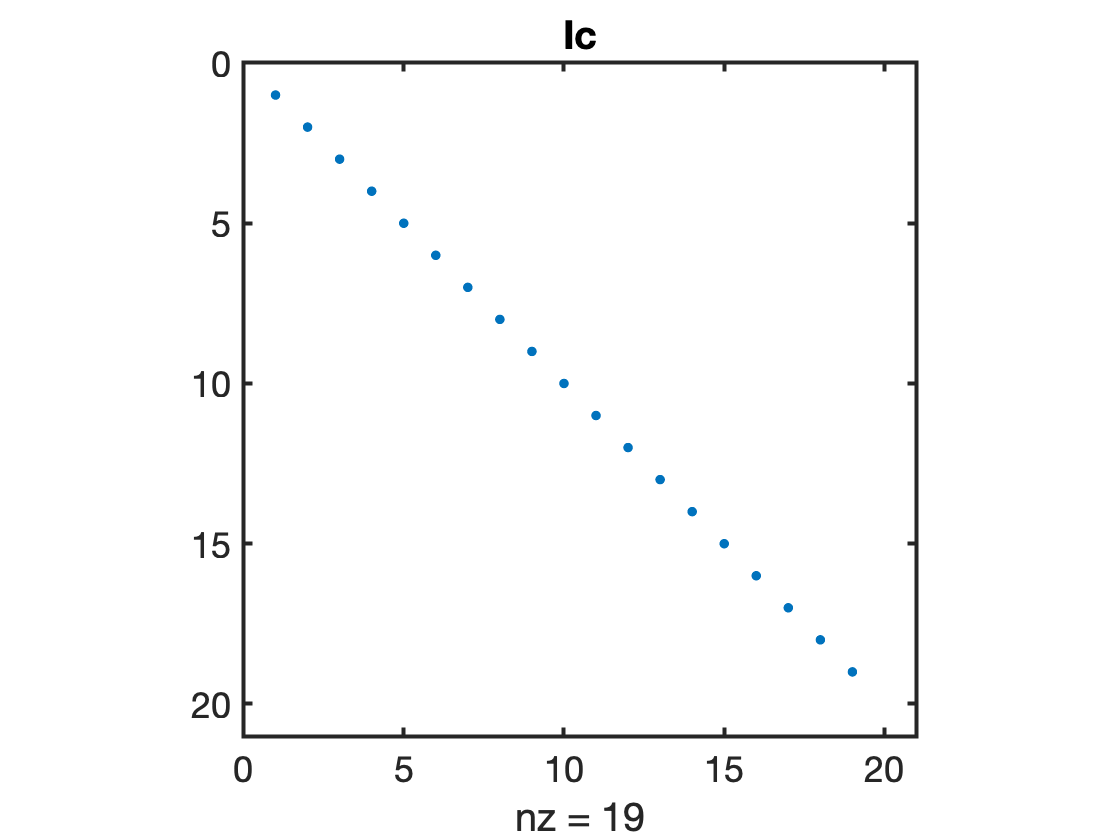

spy(Ic), title 'Ic'

non_0_entries_Ic = full(sum(diag(Ic)))

non_0_entries_Ic = 19

In this case, we have the following relationship, `N``'*``u`` = ``N``'*``N``*``ur`` = ``Ir``*``ur`` = ``ur`, so that `N` and `N`' allow us to go forth and back between `u` and `ur`:

`u`` = ``N``*``ur`

`ur`` = ``N``'*``u`

Of course, the same relationship exists between `fsr`` and ``fs, fsr ``=`` N``'*``fs`.

The matrix `N``'` *projects* the vector of unknowns into the nullspace of `B`. Note that a proper [projection matrix](https://ocw.mit.edu/courses/mathematics/18-06-linear-algebra-spring-2010/video-lectures/lecture-16-projection-matrices-and-least-squares/) is square, it would simply zero out the entries that are not in the nullspace. Instead, our `N``'` matrix eliminates these entries, but the idea is the same. 

## Reduced system matrix

Given the properties of N, defined above, the expression for the reduced system matrix is derived as follows

`L``*``u`` = ``fs`

`N``'*``L``*``u`` = ``N``'*``fs`

`N``'*``L``*``Ic``*``u`` = ``N``'*``fs`

`N``'*``L``*(``N``*`**N')**`*``u`` = ``N``'*``fs`

`(N``'*``L``*``N``)*(`**N'**`*``u)`` = ``N``'*``fs`

`Lr``*``ur`` = ``fsr`

where 

- `Lr`` = ``N``'*``L``*``N`

- `ur ``=`` N'``*``u`

- `fsr ``=`` N'``*``fs`

Lr = N'*L*N;
size(Lr)

ans =     19    19


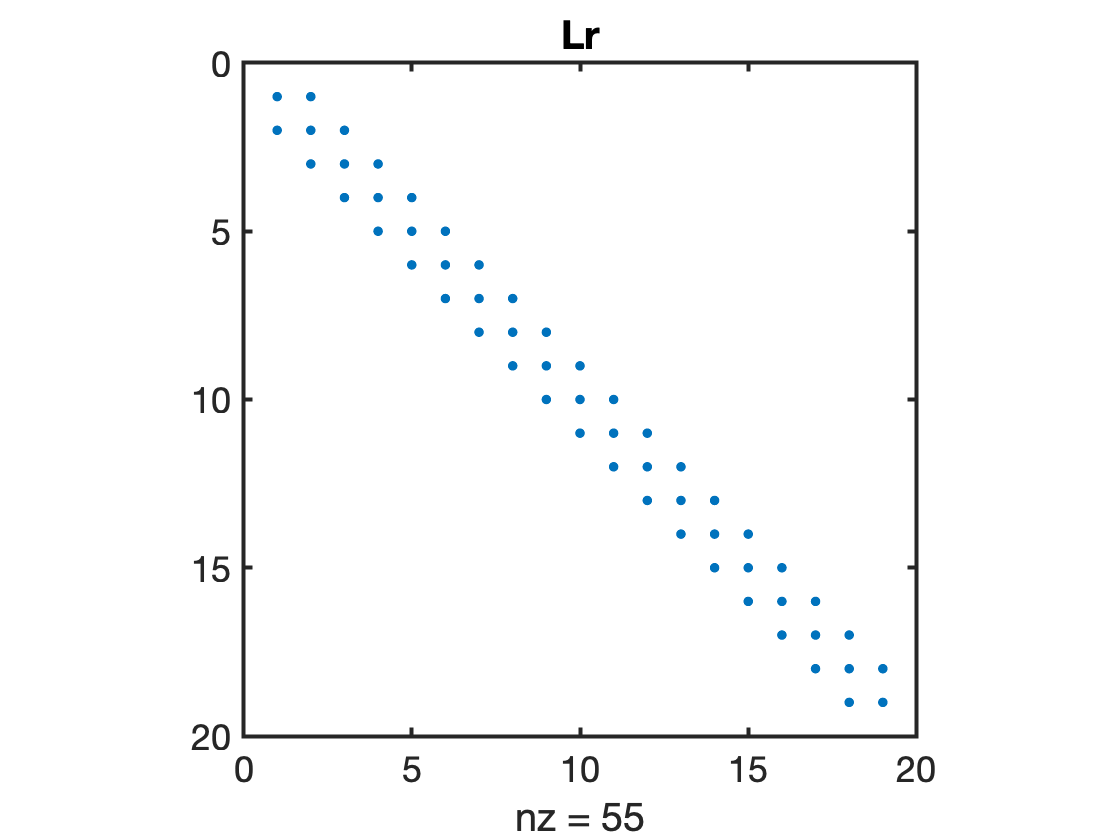

spy(Lr), title 'Lr'

The reduced system matrix Lr is not singular anymore, because the constraints have been incorporated. This can be checked by estimating the condition number

condest(Lr)

ans = 760

## Solving problem with homogeneous boundary conditions

Solving a steady problem with homogeneous boundary conditions therefore requires 3 steps:

- Compute `N` and obtain `Lr` and `fsr`.

- Solve reduced problem: `ur`` = ``Lr``\``fsr`.

- Obtain full solution: `u`` = ``N``*``ur`.

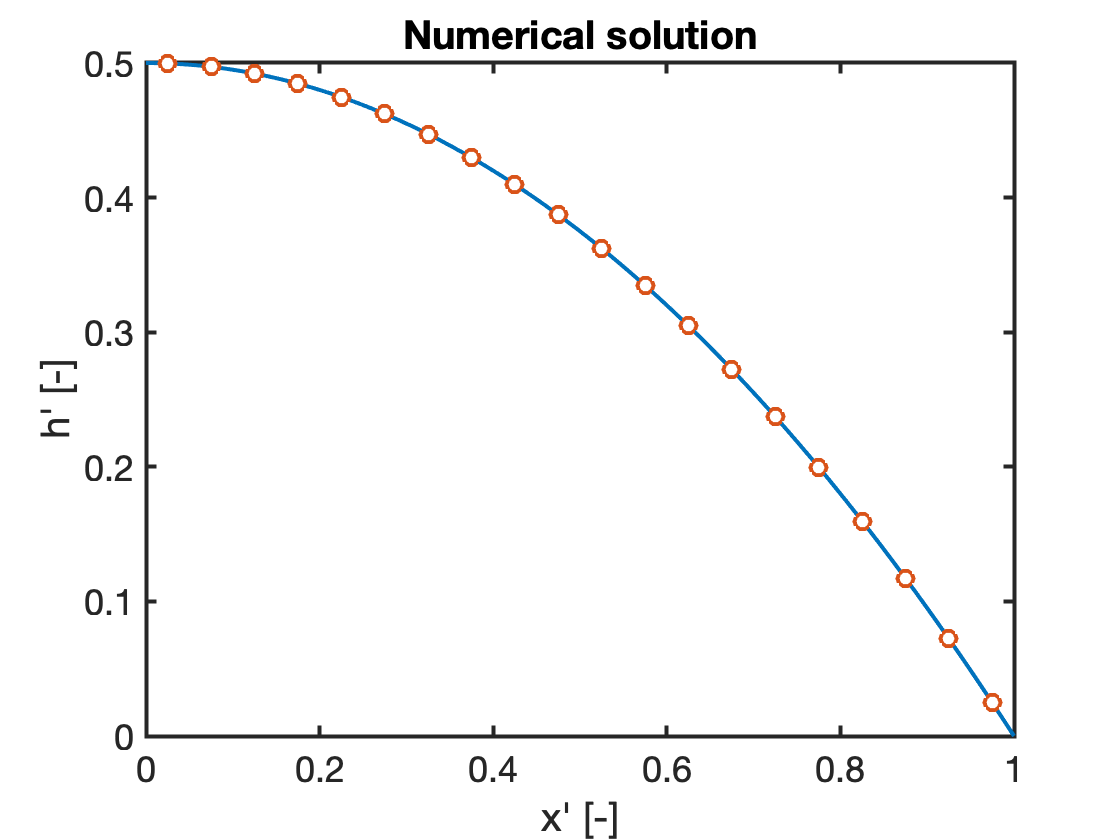

hprime = function_handle with value:
    @(xprime).5*(1-xprime.^2)


xprime =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


fs = ones(Grid.Nx,1);
fsr = N'*fs;
ur = Lr\fsr;
u = N*ur;
u = u+hprime(Grid.xc(Grid.Nx)); % shift to account for BC

clf
plot(xprime,hprime(xprime)), hold on
plot(Grid.xc,u,'o','markerfacecolor','w','markersize',8)

xlabel('x'' [-]')
ylabel('h'' [-]')
title('Numerical solution')

Note, the boundary condition is set at the center of the first cell, which makes the solution look bad (first order error).

If we shift the solution upward by the appropriate amount the fit to the analytic solution is quite good.

# Heterogeneous constraints

We are interested in solving for the geotherm which requires heterogeneous, i.e., non-zero, BC's. In this case

 `B``*``u`` = ``g`,

where `g`` = [`$T_0$`]` is a vector containing the two boundary conditions.

To obtain the solution of a problem with heterogeneous boundary conditions, we split the solution into a homogeneous and a particular solution as follows

`u`` = ``u0`` + ``up`,

where the homogeneous solution solves `B``*``u0`` = ``0` as before and the particular solution solves `B``*``up`` = ``g`. The solution then proceeds in three steps

- Find a particular solution that satisfies `B``*``up`` = ``g`.

- Find the associated homogeneous solution, `u0`.

- Find total solution `u`` = ``u0`` + ``up`.

## Find a particular solution

Note there are many possible particular solutions, here we just find the simplest one. Also not that `up` does not need to satisfy `L``*``up ``=`` fs` it only needs to satisfy the boundary conditions `B``*``up ``=`` g`. Since the system is not square and `Nx > Nc` and `B` has only `Nc` entries we can again project into a reduced space of size `Nc`. 

It is natural to use `B` as projection matrix, so that `upr`` = ``B``*``up` and `up`` = ``B'``*``upr`. We derive the reduced system as follows

`B``*``up`` = ``g`

`B``*(``B'``*``upr``) = ``g`

`(``B``*``B'``)*``upr`` = ``g`

`Br``*``upr ``=`` g`

where the reduced constraint matrix is `Br`` = ``B``*``B'` is `Nc` by `Nc`. For the simple constraints we use here `Br` is simply the `Nc` by `Nc` identity matrix, so that `upr`` = ``g`.  However, our definition is also valid for more general constraints so we'll stick with that. Once `upr` is known the full particular solution can be recovered, `up`` = ``B'``*``upr`.

## Find associated homogeneous solution

Once up is known we find the associated homogeneous solution, h0, as follows

`L``*``u`` = ``fs`

`L``*(``u0``+``up``) = ``fs`

`L``*``u0 ``=`` fs ``-`` L``*``up`

`L``*``u0 ``=`` fs + fd`

where `fd = -L``*``up `is a new source term due to heterogeneous Dirichlet BC's. But the problem can be solved with the nullspace projection for homogeneous problems as above. Combining the r.h.s. f = fs + fd we solve as follows

# Auxillary functions

This implementation of spnull() is taken from [Bruno Luong](https://www.mathworks.com/matlabcentral/profile/authors/390839-bruno-luong), thanks man!

function Z = spnull(S, varargin)
% Z = SPNULL(S)
% returns a sparse orthonormal basis for the null space of S, that is,
% S*Z has negligible elements, and Z'*Z = I
%
% If S is sparse, Z is obtained from the QR decomposition.
% Otherwise, Z is obtained from the SVD decomposition
%
% Bruno Luong <brunoluong@yahoo.com>
% History
%   10-May-2010: original version
%
% See also SPORTH, NULL, QR, SVD, ORTH, RANK

if issparse(S)
    [m n] = size(S);
    try
        [Q R E] = qr(S.'); %#ok %full QR
        if m > 1
            s = diag(R);
        elseif m == 1
            s = R(1);
        else
            s = 0;
        end
        s = abs(s);
        tol = norm(S,'fro') * eps(class(S));
        r = sum(s > tol);
        Z = Q(:,r+1:n);
    catch %#ok
        % sparse QR is not available on old Matlab versions
        err = lasterror(); %#ok
        if strcmp(err.identifier, 'MATLAB:maxlhs')
            Z = null(full(S), varargin{:});
        else
            rethrow(err);
        end
    end
else % Full matrix
    Z = null(S, varargin{:});
end

end

## set_defaults()

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end